# Perlin Noise

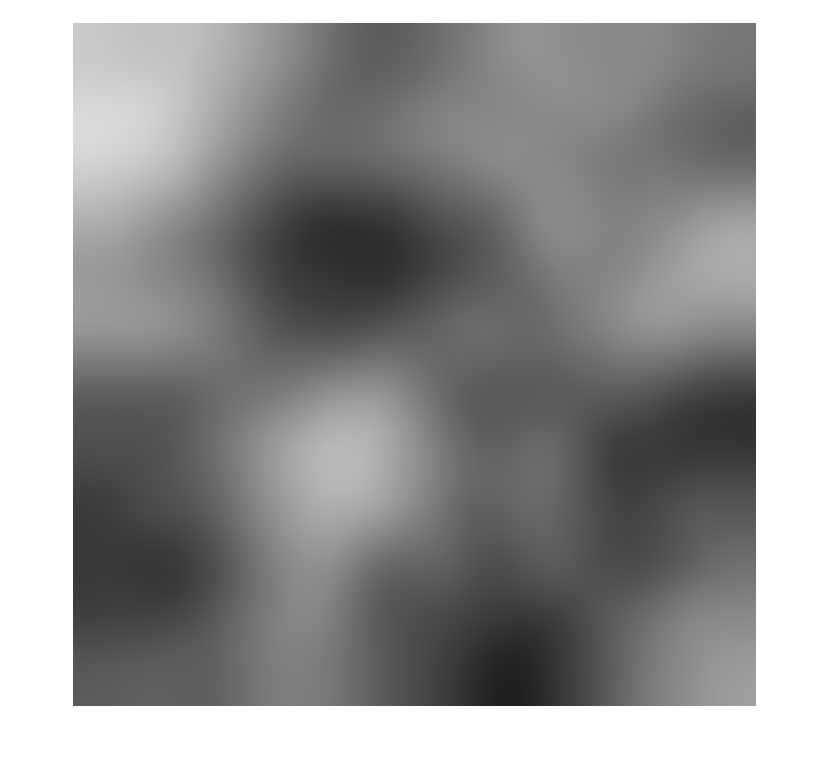

seed        =  25;
size        = 1024;
n_tiles     =    4;
n_octaves   =  24;
persistence =0.246;

rng(seed);

N       = zeros(size);
idxs    = 1:n_octaves;
max_amp = sum(persistence.^(idxs-1));

for i = idxs
    N = N + ...
        imresize(rand(n_tiles*i), ...
                [size size],"cubic")*...
        persistence^(i-1)/...
        max_amp;
end

imshow(N);
imwrite(N,"result.png");
copygraphics(gcf,"Resolution",300, ...
            "ContentType","image");

## Reference

[https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm](https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm)